% Load the model we have derived from the inversion (only for the ice shelf
% -- which means the mds model)
md = loadmodel('/Users/rishi/Desktop/ISSM-macOS-Silicon-MATLAB/examples/Pig/Models/Stange_Inverted.mat')

md =                mesh: [1x1 mesh2d]            -- mesh properties
               mask: [1x1 mask]              -- defines grounded and floating elements
           geometry: [1x1 geometry]          -- surface elevation, bedrock topography, ice thickness,...
          constants: [1x1 constants]         -- physical constants
                smb: [1x1 SMBforcing]        -- surface mass balance
      basalforcings: [1x1 basalforcings]     -- bed forcings
          materials: [1x1 matice]            -- material properties
             damage: [1x1 damage]            -- parameters for damage evolution solution
           friction: [1x1 friction]          -- basal friction/drag properties
       flowequation: [1x1 flowequation]      -- flow equations
       timestepping: [1x1 timestepping]      -- time stepping for transient models
     initialization: [1x1 initialization]    -- initial guess/state
              rifts: [1x1 rifts]             -- rifts properties
         solidearth: [1x1 s

%Apply basal mass balance conditions
paolo ='/Users/rishi/Desktop/ISSM-macOS-Silicon-MATLAB/examples/Data/Paolo_Ice_thickness_1996_2017.nc';

x = double(ncread(paolo,'x')); 
y = double(ncread(paolo,'y'));
smb_mean   = ncread(paolo,'smb_mean')'; % mean surface mass balance
bmb_mean = double(ncread(paolo,'melt_mean')); % mean basal melt rate
bmb_mean = bmb_mean';

% for the model necessity of the data roatation
y = flipud(y); 
smb_mean = flipud(smb_mean);
bmb_mean = flipud(bmb_mean);

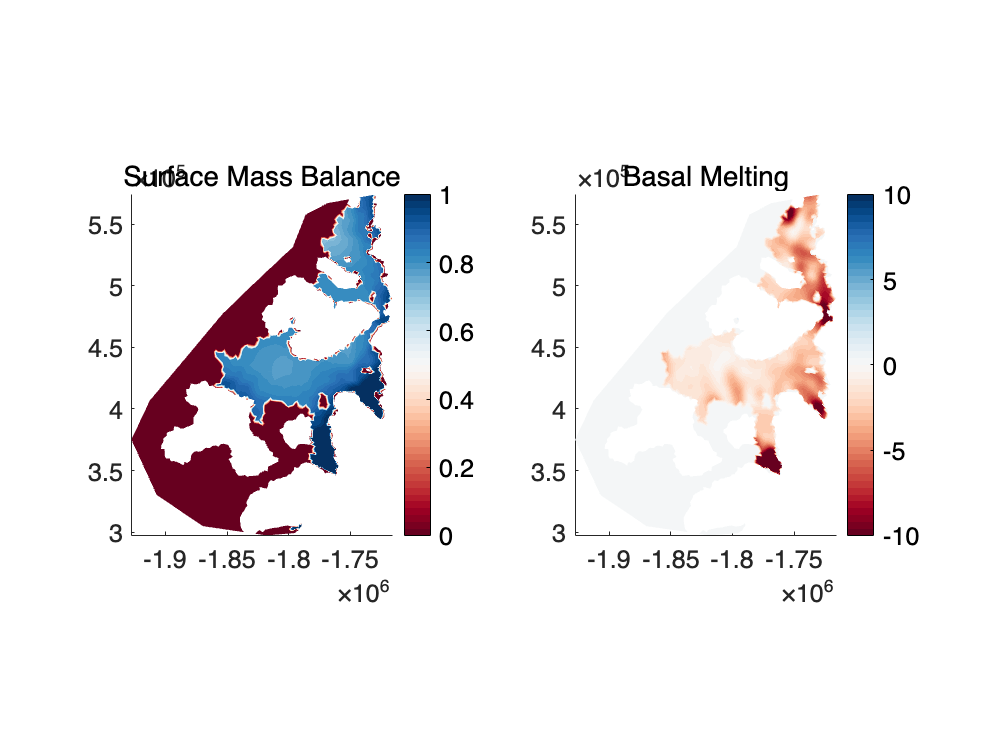

% apply surface and basal melt focing on the model for the transient run
md.smb.mass_balance = (InterpFromGridToMesh(x,y,smb_mean,md.mesh.x,md.mesh.y,0));
md.basalforcings.floatingice_melting_rate = (InterpFromGridToMesh(x,y,bmb_mean,md.mesh.x,md.mesh.y,0));
md.basalforcings.groundedice_melting_rate = zeros(md.mesh.numberofvertices,1);


% change the nan values to zero for the sake of model run
md.basalforcings.floatingice_melting_rate (isnan(md.basalforcings.floatingice_melting_rate)) = 0;
md.smb.mass_balance (isnan(md.smb.mass_balance)) = 0;


%check whether the surface mass baalance is properly implemented
plotmodel(md,'data',md.smb.mass_balance,'title','Surface Mass Balance','caxis#1',([0 1]),...
    'data',md.basalforcings.floatingice_melting_rate,'title','Basal Melting','caxis#2',([-10 10]))

colormap(brewermap(50,'RdBu'))

%Indicate the components of transient to activate
md.transient.ismasstransport = 1;
md.transient.isstressbalance = 1;
md.transient.isgroundingline = 1;
md.transient.ismovingfront = 0;
md.transient.isthermal = 0;

%Specify time steps and length of simulation (years)
md.timestepping.start_time = 0;
md.timestepping.time_step = 0.1;
md.timestepping.final_time = 20;

%Disable inverse method
md.inversion.iscontrol = 0;

%Initialize fields for transient and add boundary conditions
md.initialization.vx = md.results.StressbalanceSolution.Vx;
md.initialization.vy = md.results.StressbalanceSolution.Vy;
md.initialization.vel = md.results.StressbalanceSolution.Vel;
md.masstransport.spcthickness = NaN * ones(md.mesh.numberofvertices,1);

%Request additional outputs
md.transient.requested_outputs = {'default','IceVolume','IceVolumeAboveFloatation','TotalSmb','TotalFloatingBmb'};

% Solve transient
md.cluster = generic('name',oshostname,'np',4);
md.verbose = verbose('solution',false);
md = solve(md,'Transient');

launching solution sequence

Ice-sheet and Sea-level System Model (ISSM) version  4.24
(website: http://issm.jpl.nasa.gov forum: https://issm.ess.uci.edu/forum/)

call computational core:
write lock file:

   FemModel initialization elapsed time:   0.019712
   Total Core solution elapsed time:       50.9625
   Linear solver elapsed time:             40.6984 (80%)

   Total elapsed time: 0 hrs 0 min 50 sec


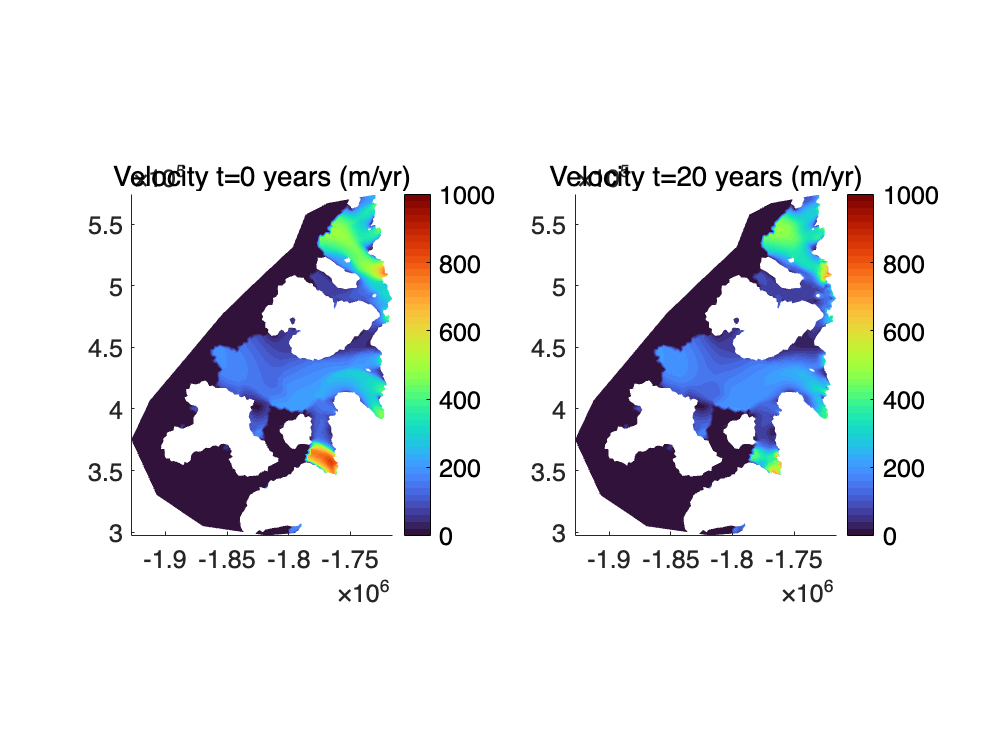

%Plot results
plotmodel(md, 'data', md.results.TransientSolution(1).Vel,'title#1', 'Velocity t=0 years (m/yr)',...
  'data', md.results.TransientSolution(end).Vel,'title#2', 'Velocity t=20 years (m/yr)',...
  'caxis#1',([0 1000]),'caxis#2',([0 1000]));

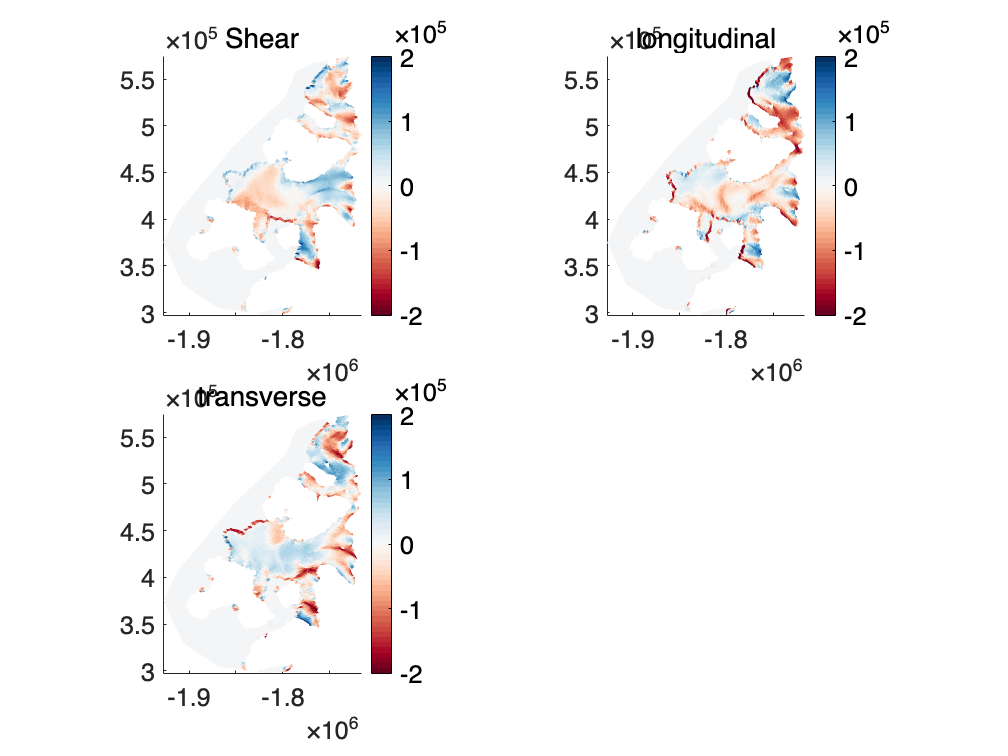

% try to produce the mechanical properties of an ice shelf from the
% transient run

% This is the stress and strain output of the first year before run
vx1 = md.results.TransientSolution(1).Vx;
vy1 = md.results.TransientSolution(1).Vy;
md = mechanicalproperties(md, vx1, vy1);
md.results.deviatoricstress_start = md.results.deviatoricstress;

% This is the stress and strain output of the end year after run
vxt = md.results.TransientSolution(end).Vx;
vyt = md.results.TransientSolution(end).Vy;
md = mechanicalproperties(md, vxt, vyt);
md.results.deviatoricstress_end = md.results.deviatoricstress;


%% plotting the Deviatoric Stresses for the last year
plotmodel(md,'data',md.results.deviatoricstress_start.xy,'title','Shear',...
'data',md.results.deviatoricstress_start.xx,'title','longitudinal',...
'data',md.results.deviatoricstress_start.yy,'title','transverse','caxis#all',[-2e5 2e5]);
colormap(brewermap(50, 'RdBu'));


% ====== USER INPUT ======
which_time = 'start';  % options: 'start' or 'end'
time_index = 1;        % default to first (can change to final index later)

% if the user select end get the end from the length(TransientSolution)
if strcmp(which_time, 'end')
    time_index = length(md.results.TransientSolution);
end

% Recover velocity
vx = md.results.TransientSolution(time_index).Vx;
vy = md.results.TransientSolution(time_index).Vy;

% Compute mechanical properties
md = mechanicalproperties(md, vx, vy);
md.results.deviatoricstress_current = md.results.deviatoricstress;

% Constants
g = md.constants.g;
rho_i = md.materials.rho_ice;
rho_w = md.materials.rho_water;

% Element-averaged quantities
H = mean(md.geometry.thickness(md.mesh.elements), 2);
depth = mean(md.geometry.base(md.mesh.elements), 2) - mean(md.geometry.bed(md.mesh.elements), 2);
vx_el = mean(vx(md.mesh.elements), 2);
vy_el = mean(vy(md.mesh.elements), 2);

% Allocate outputs
n_el = md.mesh.numberofelements;
Kn = NaN(n_el, 1);
Backstress_Furst = NaN(n_el, 1);

for el = 1:n_el
    % Decompose deviatoric stress
    tau_xx = md.results.deviatoricstress_current.xx(el);
    tau_yy = md.results.deviatoricstress_current.yy(el);
    tau_xy = md.results.deviatoricstress_current.xy(el);

    % Build 2D stress tensor
    R = [2*tau_xx + tau_yy, tau_xy;
         tau_xy, 2*tau_yy + tau_xx];

    % Choose stress direction (flow or principal axis)
    use_flow_direction = false;  % set to true for "flow buttressing"

    if use_flow_direction
        vec = [vx_el(el); vy_el(el)];
    else
        vec = md.results.deviatoricstress_current.principalaxis2(el, :)';
    end

    % Normalize direction vector
    if norm(vec) == 0
        continue;
    end
    n = vec / norm(vec);

    % Compute projected stress and buttressing number
    N = n' * R * n;
    N0 = 0.5 * g * rho_i * (1 - rho_i / rho_w) * H(el);

    Kn(el) = 1 - N / N0;
    Backstress_Furst(el) = N0 - N;
end

% Optional: rename based on time
if strcmp(which_time, 'start')
    Kn_start = Kn;
    Backstress_Furst_start = Backstress_Furst;
elseif strcmp(which_time, 'end')
    Kn_end = Kn;
    Backstress_Furst_end = Backstress_Furst;
end

Backstress_Furst_end(Backstress_Furst_end == 0) =nan;
Backstress_Furst_start(Backstress_Furst_start == 0) =nan;


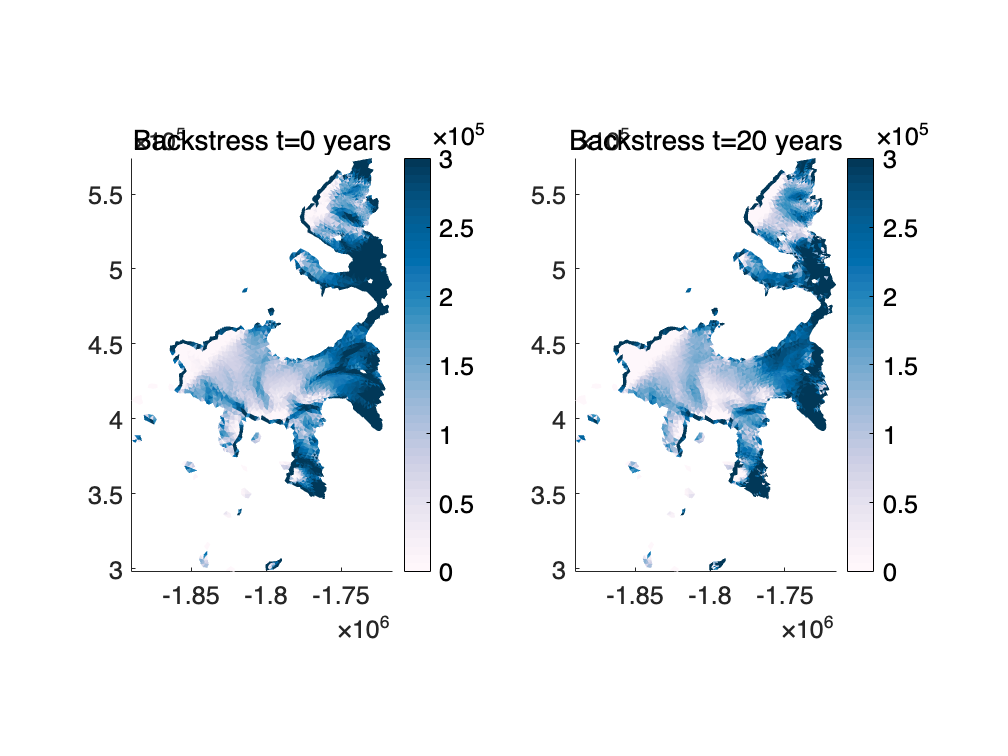

% Plot them and show the difference between them
plotmodel(md,'data',Backstress_Furst_start,'title', 'Backstress t=0 years','caxis#1',[0 3e5], ...
              'data',Backstress_Furst_end,'title', 'Backstress t=20 years','caxis#2',[0 3e5])

colormap(brewermap(50,'PuBu'))